#### Based on the research paper by Department of Health and Human Resources - USA

#### Name of the paper- Compression Fitting of Hearing Aids and Implementation

#### Authors- Kashyap Patel, Issa M. S. Panahi 

% Compression technique implementation
[x,Fs] = audioread("Classical.wav");

xr = resample(x,16000,Fs);
fs = 16000;

frameLen = 256;
hop = 128;
fftLen = 1024;
%Compression parameters
T = 65; % Compression threshold in dB SPL
CR = 2; % Compression ratio
W = 20; % Knee width in dB
M = 0; % Makeup gain in dB

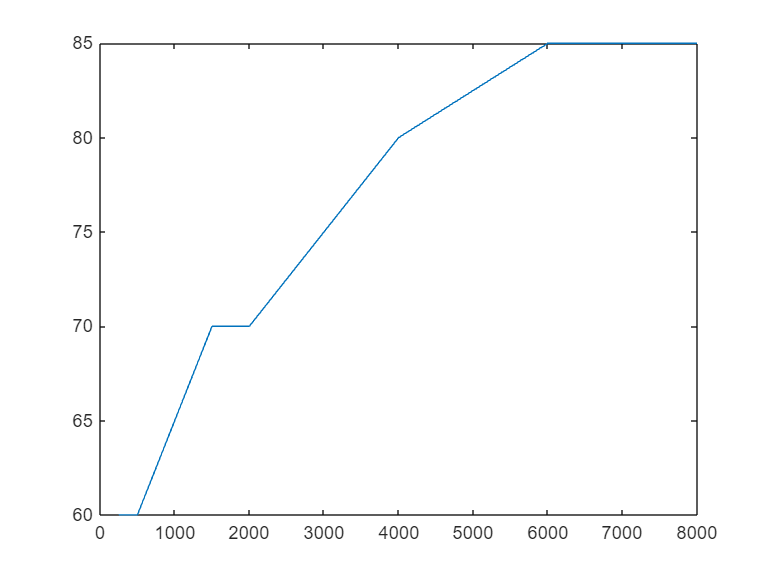

freqBands = [250 500 1000 1500 2000 3000 4000 6000 8000];
hearingLoss = [60 60 65 70 70 75 80 85 85]; % dB 
figure;
plot(freqBands,hearingLoss)

insertionGain = hearingLoss / 2;
% Extra corrections for low frequencies
insertionGain(1) = insertionGain(1) - 10;
insertionGain(2) = insertionGain(2) - 5;

win = hann(frameLen, 'periodic');

[S, F, Tframes] = stft(xr, fs,'Window', win,'OverlapLength', frameLen-hop,'FFTLength', fftLen);

mag = abs(S);
mag_dB = 20 * log10(mag + 1e-8);

gainInterp = interp1(freqBands, insertionGain, F, 'linear', 'extrap');
gainInterp = gainInterp(:);
staticGainMatrix = repmat(gainInterp, 1, size(S,2));
magGain_dB = mag_dB + staticGainMatrix;

VG = zeros(size(magGain_dB));

for i = 1:size(magGain_dB,1)
    for j = 1:size(magGain_dB,2)
        XG = magGain_dB(i,j);

        if 2*(XG - T) <= -W
            VG(i,j) = XG;

        elseif abs(2*(XG - T)) < W
            VG(i,j) = XG + ((1/CR - 1) * (XG - T + W/2)^2) / (2*W);

        else
            VG(i,j) = T + (XG - T)/CR;
        end
    end
end

compressionGain_dB = VG - magGain_dB;

% Attack/release times
attack_ms = 10;
release_ms = 100;

tauA = attack_ms / 1000;
tauR = release_ms / 1000;

alphaA = exp(-hop / (tauA * fs));
alphaR = exp(-hop / (tauR * fs));

smoothedCompressionGain = zeros(size(compressionGain_dB));

for i = 1:size(compressionGain_dB,1)

    smoothedCompressionGain(i,1) = compressionGain_dB(i,1);

    for j = 2:size(compressionGain_dB,2)

        currentGain = compressionGain_dB(i,j);
        previousGain = smoothedCompressionGain(i,j-1);

        % Faster response when more compression is needed
        if currentGain < previousGain
            smoothedCompressionGain(i,j) = alphaA * previousGain + (1 - alphaA) * currentGain;
        else
            smoothedCompressionGain(i,j) = alphaR * previousGain + (1 - alphaR) * currentGain;
        end

    end
end

spectralFlux = zeros(1, size(mag,2));

for j = 2:size(mag,2)
    spectralFlux(j) = mean((mag(:,j) - mag(:,j-1)).^2);
end

totalGain_dB = staticGainMatrix + smoothedCompressionGain + M;

gainLinear = 10.^(totalGain_dB/20);
Sout = S .* gainLinear;
y = real(istft(Sout, fs, 'Window', win,'OverlapLength', frameLen-hop,'FFTLength', fftLen));

y = y/max(y);

N = size(xr);
t = 0:1/fs:(N/fs-1/fs);

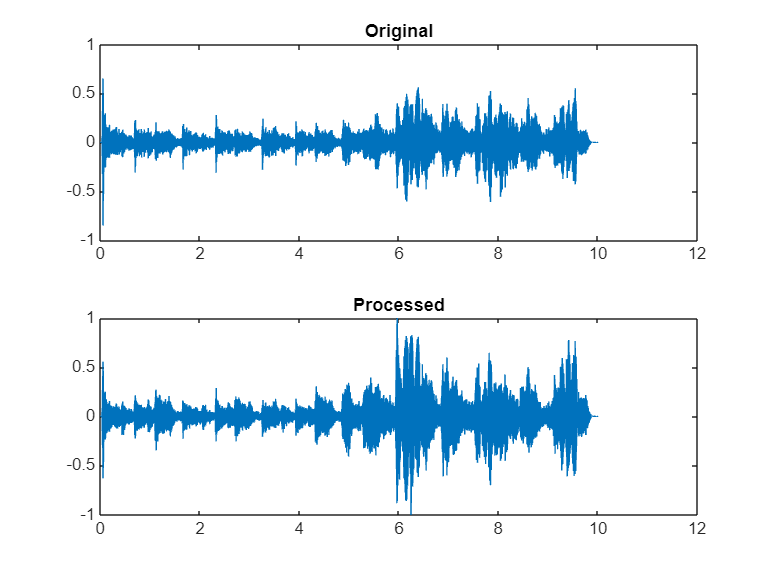

figure;
subplot(2,1,1)
plot(t,xr)
title('Original')

subplot(2,1,2)
plot(t(1:160128),y')
title('Processed')

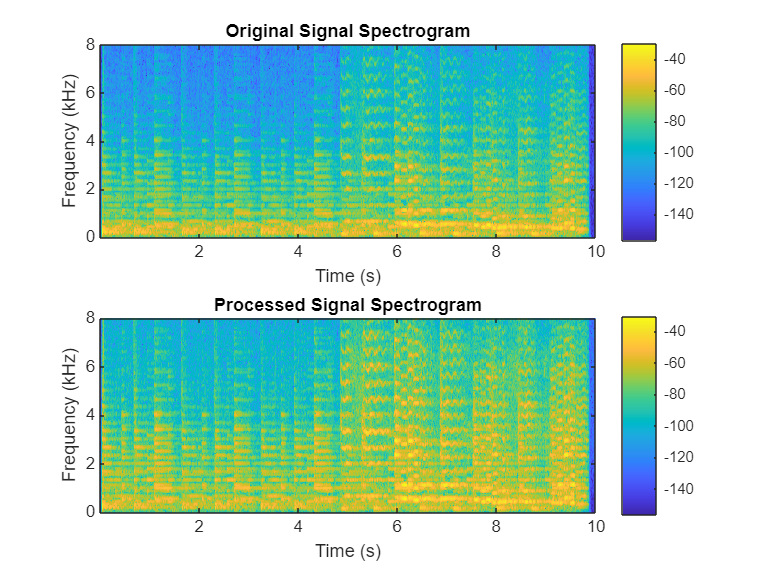

figure;

% Spectrogram parameters
window = hann(256);
noverlap = 128;
nfft = 1024;

% Original signal
subplot(2,1,1);
spectrogram(xr, window, noverlap, nfft, fs, 'yaxis');
title('Original Signal Spectrogram');
colorbar;

% Processed signal
subplot(2,1,2);
spectrogram(y, window, noverlap, nfft, fs, 'yaxis');
title('Processed Signal Spectrogram');
colorbar;

%sound(xr,fs)
sound(y,fs)